# t_wvfMTF

We illustrate how to calculate PSFs and MTFs using the wavefront tools.  We do this for the diffraction limited case first, including various levels of defocus.  Then we run an example with a human eye wavefront.

ieInit

## Create the diffraction-limited wavefront object

The wavefront struct, along wvfGet/Set/Plot, manage the wavefront calculations.

wvf0 = wvfCreate;   % Create a default struct

The wavefront data were measured with some parameters.  We do our calculations with parameters within the bounds of the measurements.

wave = 550;
wvf0 = wvfSet(wvf0, 'measured wavelength', wave);
wvf0 = wvfSet(wvf0, 'calc wavelengths', wave);

Calculate the PSF (and OTF) for the default wavefront parameters. The key parameters are wavelength and Zernike polynomial coefficients.

wvf0 = wvfCompute(wvf0);

## Vary defocus and plot a slice through the PSF

Set the defocus in diopters by adjusting the Zernike polynomial term for 'defocus'.  We recompute the PSF and plot a slice through the PSF function.

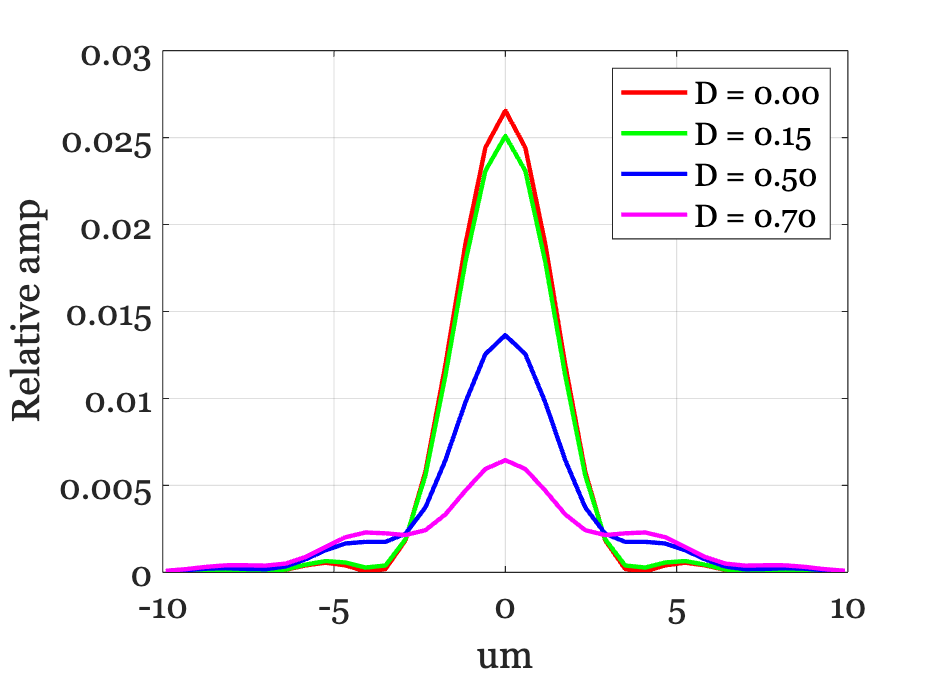

ieNewGraphWin;
d = [0 , 0.15, 0.5, 0.7];  % Defocus in diopters
thisL = cell(length(d),1);

for ii=1:length(d)
    wvf1 = wvfSet(wvf0,'zcoeffs',d(ii),{'defocus'});  % Change the defocus coefficient
    wvf1 = wvfCompute(wvf1);

    wvfPlot(wvf1, '1d psf', 'unit','um', 'plot range', 10, 'window', false);
    hold on;
    thisL{ii} = sprintf('D = %0.2f',d(ii));
end

hold off
xlabel('um'); ylabel('Relative amp'); grid on
legend(thisL);

## Compare the two pointspread functions (PSF)

We compare defocus of 0 and 0.5 diopters.  We would like to have some method of confirming that the defocus of 0.5 diopters produces this amount of spread.

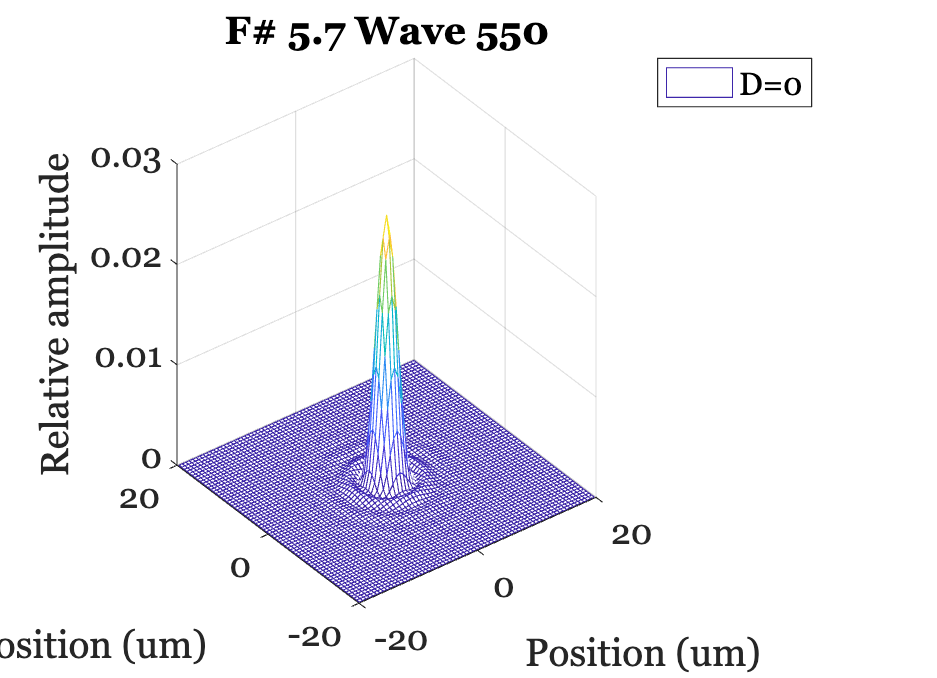

wvfPlot(wvf0, 'psf', 'unit','um', 'plot range', 20);
legend({'D=0'})

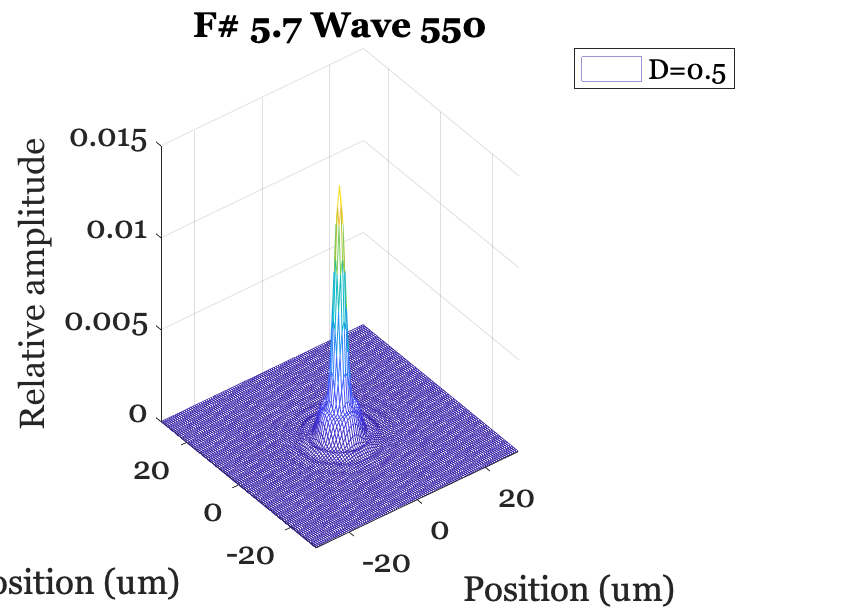

% Defocus of 0.5 diopters
thisD = 0.5;
wvf1 = wvfSet(wvf0,'zcoeffs',thisD,{'defocus'});
wvf1 = wvfCompute(wvf1);
wvfPlot(wvf1, 'psf', 'unit','um', 'plot range', 30);
legend({sprintf('D=%1.1f',thisD)})

## The impact of defocus on the amplitude of the OTF (MTF) with respect to cycles/mm

We use the same defocus parameters, starting from d=0 (diffraction limited) and then increasing.

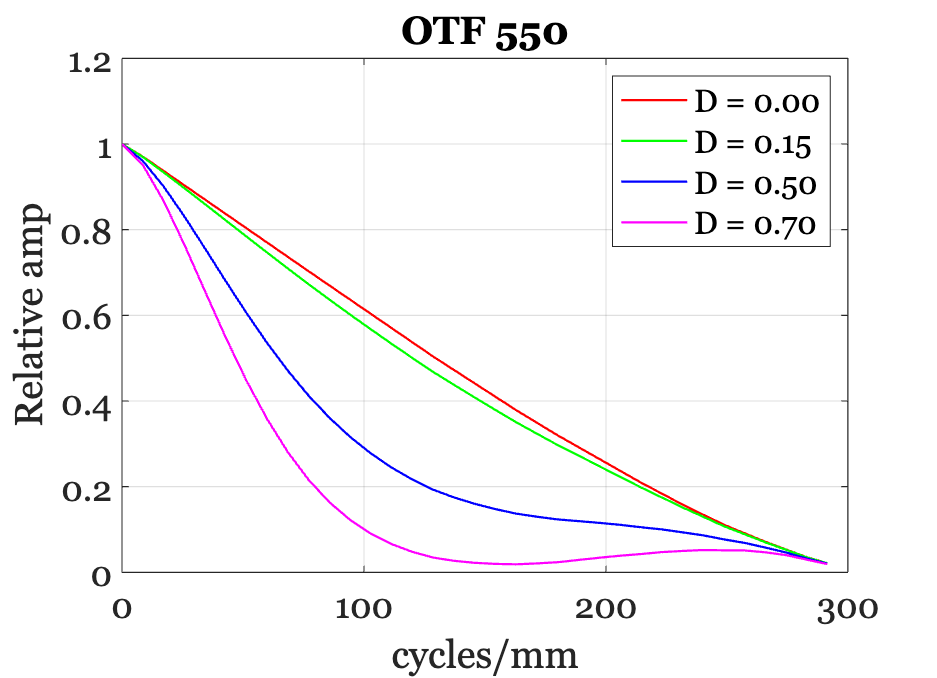

ieNewGraphWin;
for ii=1:length(d)
    wvf1 = wvfSet(wvf0,'zcoeffs',d(ii),{'defocus'});
    wvf1 = wvfCompute(wvf1);
    wvfPlot(wvf1, '1d otf', 'plot range', 300, 'window', false);
    hold on;
    thisL{ii} = sprintf('D = %0.2f',d(ii));
end

hold off
xlabel('cycles/mm'); ylabel('Relative amp'); grid on
legend(thisL);

## The amplitude of the OTF (i.e., MTF) with respect to cycles per degree

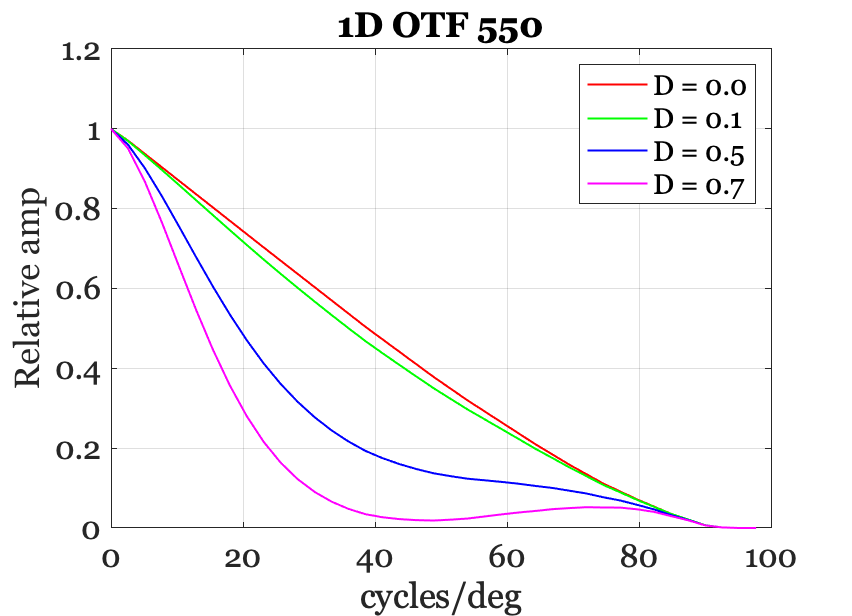

ieNewGraphWin;
for ii=1:length(d)
    wvf1 = wvfSet(wvf0,'zcoeffs',d(ii),{'defocus'});
    wvf1 = wvfCompute(wvf1);
    wvfPlot(wvf1, '1d otf angle', 'unit','deg', 'plot range', 100, 'window', false);
    hold on;
    thisL{ii} = sprintf('D = %0.1f',d(ii));
end

hold off
xlabel('cycles/deg'); ylabel('Relative amp'); grid on
legend(thisL);

## Calculate using human wavefront measurements

First we read the Zernike coefficients from a dataset stored in ISETBio

pupilDiameterMM = 3;

% Thibos just provides the Zernike polynomial coefficients at
% different diameters
zCoefs = wvfLoadThibosVirtualEyes(pupilDiameterMM);

wave = 550;
umPerDegree = 300;

Create wavefront parameters. Be sure to set both measured and  calc pupil size.

wvfP = wvfCreate('calc wavelengths', wave, 'zcoeffs', zCoefs, ...
    'name', sprintf('human-%d', pupilDiameterMM), ...
    'umPerDegree', umPerDegree);
wvfP = wvfSet(wvfP, 'measured pupil size', pupilDiameterMM);
wvfP = wvfSet(wvfP, 'calc pupil size', pupilDiameterMM);

Calculate and plot the OTF/PSF

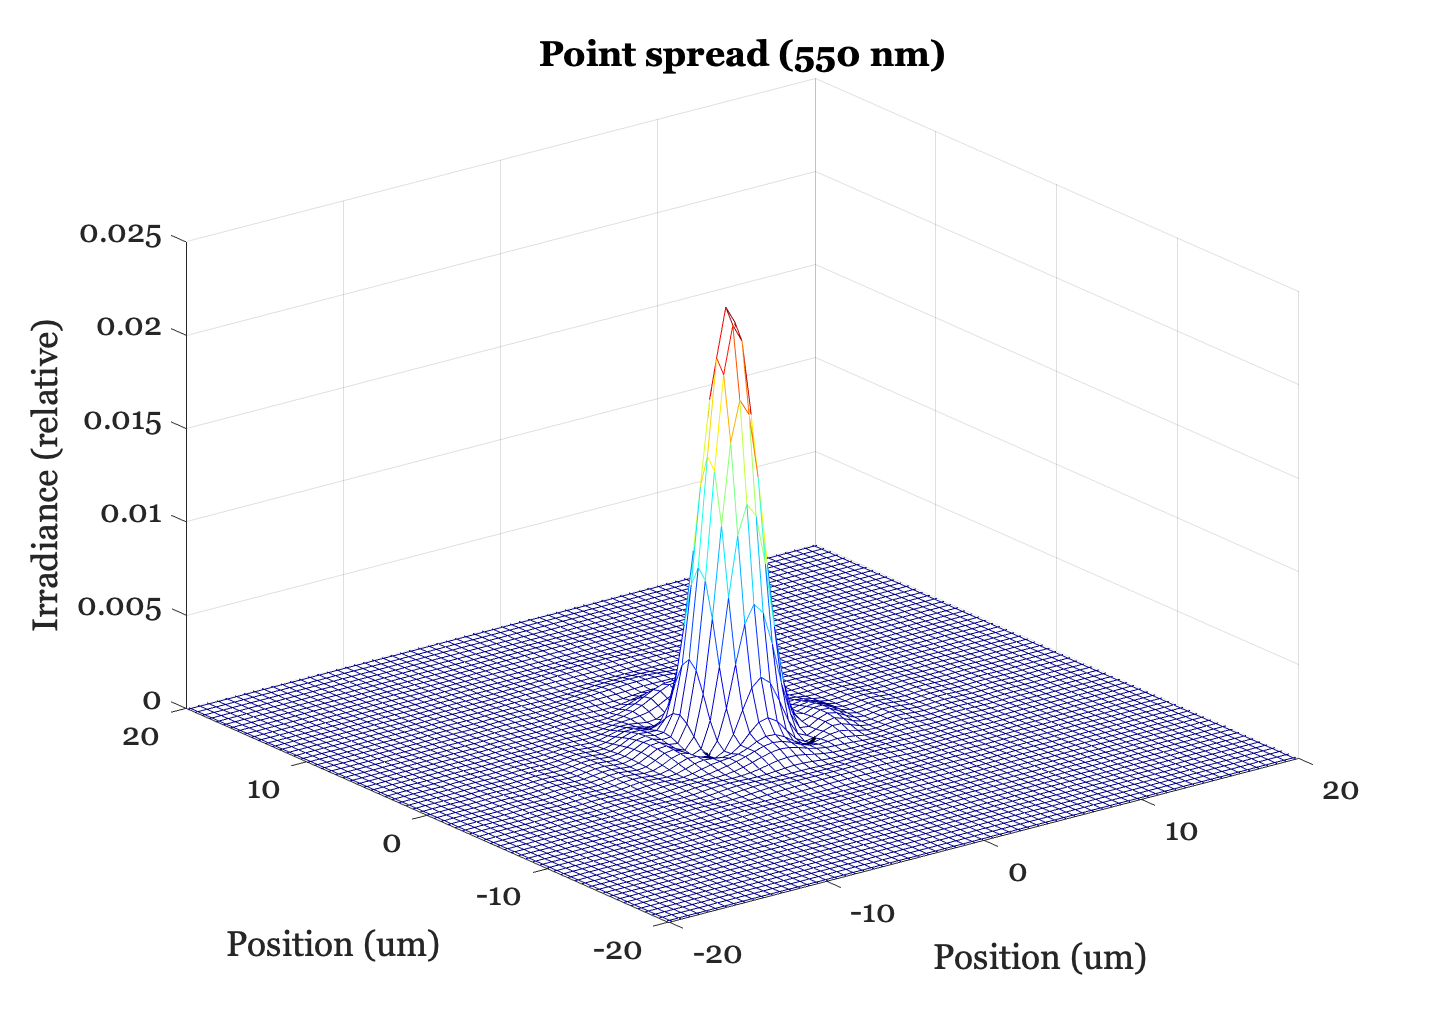

wvfP = wvfCompute(wvfP);
oi = wvf2oi(wvfP,'model','human');
oiPlot(oi,'PSF',[],550,'airydisk',true); 
set(gca,'xlim',[-20 20],'ylim',[-20 20]); 

## Now plot the MTF after add increasing the defocus of the human eye model

BW: I was surprised that increasing the defocus of the human eye has a different impact from increasing of the diffraction limited case.  But then I realize, I shouldn't be.  When you defocus by 1 diopter the impact of that defocus should depend on the level you are starting.

First, have a look at the one dimensional cuts through the OTF.  They differ from the diffraction limited case.

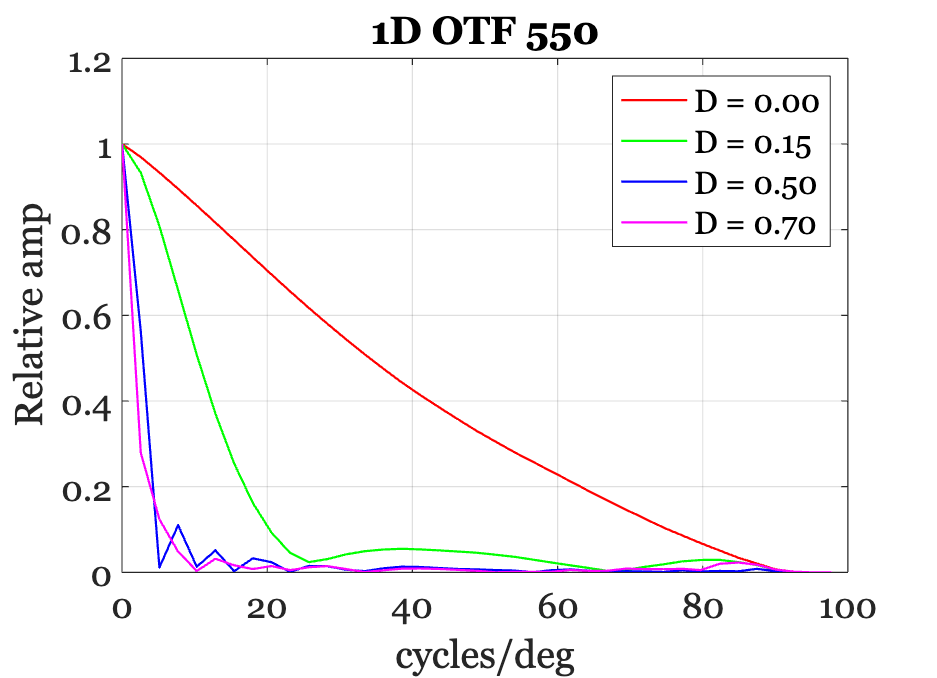

ieNewGraphWin;
for ii=1:length(d)
    wvfP = wvfSet(wvfP,'zcoeffs',d(ii),{'defocus'});
    wvfP = wvfCompute(wvfP);
    wvfPlot(wvfP, '1d otf angle', 'unit','deg', 'plot range', 100, 'window', false);
    hold on;
    thisL{ii} = sprintf('D = %0.2f',d(ii));
    % disp(wvfGet(wvfP,'zcoeffs')');
end

hold off
xlabel('cycles/deg'); ylabel('Relative amp'); grid on
legend(thisL);

Here we see that the pointspread function with 0.5 diopters of defocus is very different in this case than the original diffraction limited case above.  So the defocus imposed on the typical human eye is different from the defocus imposed on the diffraction limited lens.  More thinking about this is called for.

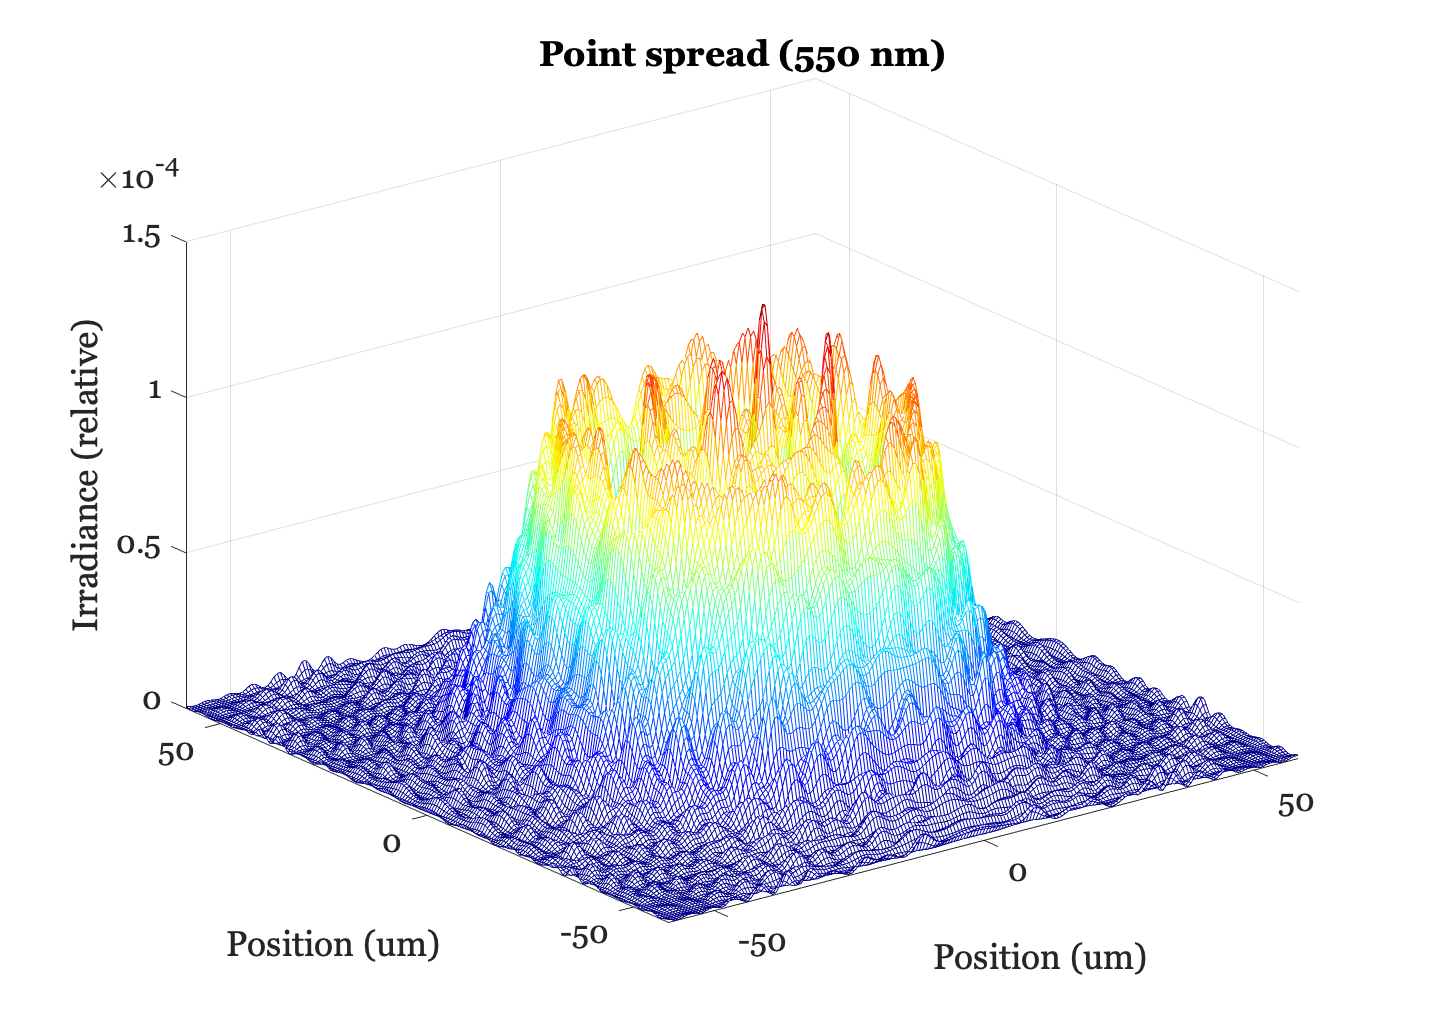

wvfP = wvfSet(wvfP,'zcoeffs',0.5,{'defocus'});
wvfP = wvfCompute(wvfP);
oi = wvf2oi(wvfP,'model','human');
oiPlot(oi,'PSF',[],550,'airydisk',false);